# An Overview of Machine Learning for Science and Engineering

[⇦ Main Menu](matlab:open('../../MainMenu.mlx'))

In this script, we explore how machine learning helps uncover patterns in complex biological data, enabling various solutions across science and engineering.

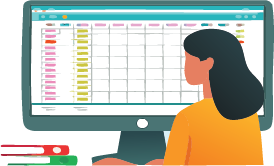

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is Machine Learning?

**Machine learning** is a method by which computers learn from data through training to make predictions or decisions without being explicitly programmed. Unlike traditional statistical approaches, where we define a specific model based on hypotheses about the data, **machine learning** allows the computer to discover patterns and relationships directly from the data.

If we observe a linear trend between two variables, we might hypothesize a linear relationship and test it using a linear regression model. This approach requires us to specify the model structure in advance and then estimate its parameters from the data.

In contrast, **machine learning** involves selecting a general model structure such as a decision tree or neural network. The algorithm then learns the optimal parameters from the data. For example, we can train a machine learning model using labeled images. If we provide pictures of dogs labeled "dog" and pictures of cats labeled "cat," the algorithm identifies distinguishing patterns and builds a model that can classify new, unlabeled images. This model functions as a set of learned rules, such as "This is a cat," or "This is a dog," that convert input data into accurate predictions.

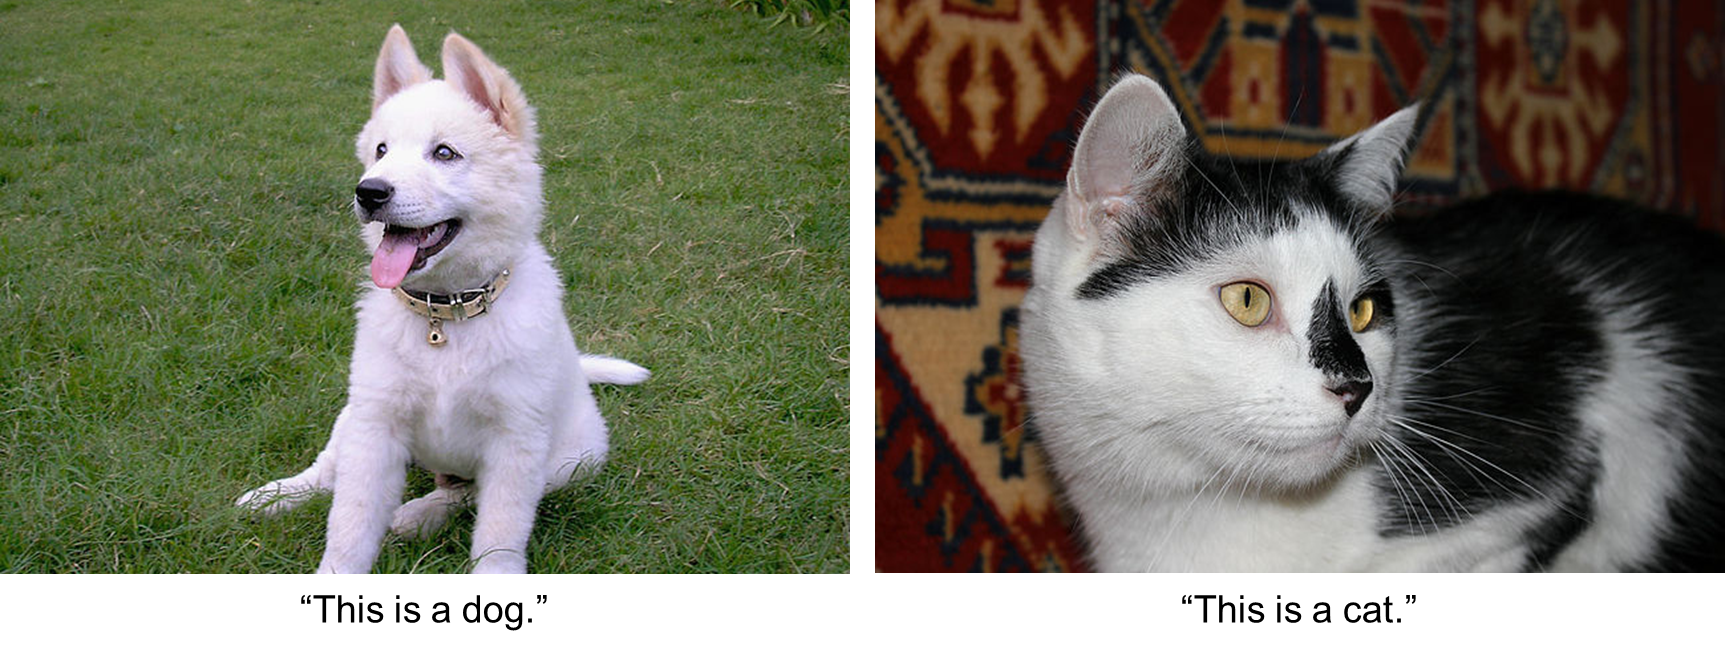

*Image Source (Dog): *[*Imk0278 at English Wikipedia*](https://commons.wikimedia.org/wiki/File:Kintamani_dog_white.jpg)*, Public domain, via Wikimedia Commons. Image Source (Cat):*[*George Chernilevsky*](https://upload.wikimedia.org/wikipedia/commons/2/29/Domestic_cat_2011_G01.jpg)*, Public domain, via Wikimedia Commons.*

 **Understanding Check 1.**

CheckAnswer("Exercise1","To recognize patterns in data and make predictions.");  

## **Why use Machine Learning?**

### **In Biology and the Sciences**

Much of the data collected in modern research and clinical settings is high-dimensional and complex. Datasets often include hundreds of samples and just as many variables, or "predictors," used to describe each case, such as patient intake data in a hospital may include variables such as height, weight, smoking and drinking habits, diet, and family medical history.

Suppose the goal is to predict a patient's risk of heart attack. Identifying the most relevant predictors from a large set of variables can be difficult without computational support. Machine learning enables automated data analysis and prediction, allowing us to uncover insights that would be difficult to achieve manually.

Machine learning has a wide range of applications in biosciences, revolutionizing how research is conducted and interpreted. Beyond clinical risk prediction, machine learning has numerous applications in biology. Other applications include: drug development, disease diagnosis and prognosis, microarray data analysis, systems biology, and more.

In addition to the biosciences, machine learning is widely applied across other scientific disciplines. In environmental science, it supports climate modeling, seismology, and remote sensing. It accelerates materials discovery, enhances molecular simulations, and streamlines spectroscopy analysis in chemistry. Even in the social sciences, machine learning is used to model complex systems in economics, analyze trends in political science, and study patterns in sociology. Across these fields, machine learning offers the advantages of automating data analysis, uncovering hidden patterns, improving predictive accuracy, and enabling discoveries.

 **Understanding Check 2. **

CheckAnswer("Exercise2","It enhances the ability to interpret complex data and make predictions.");  

### In Engineering

Engineers routinely collect large datasets with hundreds or thousands of variables ranging from sensor readings and control parameters to material properties and environmental conditions.

Suppose the goal is to optimize the performance of an electric motor, predict equipment failure, or control a robotic arm in real time. Identifying the most influential factors from a large set of inputs can be challenging without computational tools. Machine learning enables automated analysis, pattern recognition, and prediction, making it possible to extract actionable insights from complex datasets that would be difficult to interpret manually.

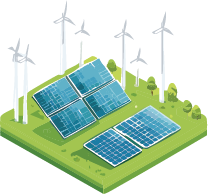

Machine learning transforms engineering disciplines by enabling smarter design, diagnostics, and control. In electrical engineering, it is used for power load forecasting, fault detection in smart grids, and signal processing. It delivers greater accuracy, enables early fault detection, and supports adaptive signal analysis, resulting in improved system efficiency and reliability. In mechanical engineering, it is applied in predictive maintenance, structural health monitoring, and fluid dynamics optimization, enabling early failure prediction, reduced downtime, and faster, data-driven design improvements. In chemical engineering, it supports process control, reaction yield prediction, and materials discovery, providing better process efficiency, safer operations, and accelerated innovation in chemical formulations. In robotics and automation, it powers real-time decision-making, adaptive control, and autonomous navigation, resulting in more intelligent, flexible, and responsive robotic systems.

 **Understanding Check 3.**

CheckAnswer("Exercise9","It helps analyze complex datasets and identify key patterns.");  

## **Types of Machine Learning**

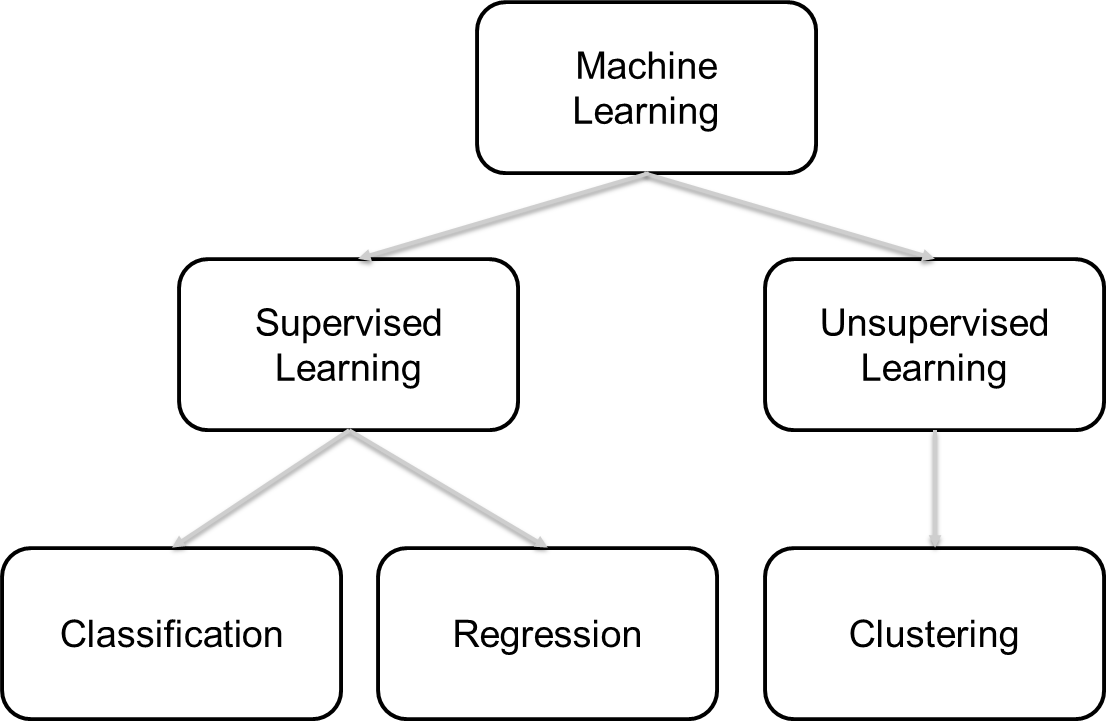

Machine learning can be broadly categorized into two main types: **supervised learning** and **unsupervised learning**, both of which can be illustrated using the example of distinguishing between cats and dogs.

### Unsupervised Learning

If we have a set of unlabeled images of dogs and cats, we could try **unsupervised learning**, With unsupervised learning**, **the algorithm is given a set of unlabeled images of cats or dogs. It analyzes the features of each image and groups similar features together based on shared characteristics. For instance, it might cluster images with pointed ears and slender bodies into one group, and those with floppy ears and broader faces into another. While the algorithm doesn't know the names of the categories, it uncovers the underlying structure in the data by identifying natural groupings or **clustering**.

### Supervised Learning

If we have a set of images that are each labeled "dog" or "cat", we could try **supervised learning****. **With supervised learning an algorithm is trained on a dataset that includes both input data and the correct output labels. For example, if the algorithm is given a collection of images labeled as either "cat" or "dog," it learns to associate specific visual features such as ear shape, fur texture, or body size, with each label. Once trained, the model can classify new, unlabeled images by applying the learned patterns. This process is similar to studying with an answer key: the algorithm learns from examples where the correct answers are already known.

### Classification and Regression

**Supervised learning** typically falls into two main categories: **classification** and **regression**. Classification is used when the output variable consists of distinct categories or labels, such as "true" or "false," or "low," "medium," and "high." In this case, the goal is to predict a class label. In contrast, regression is used when the output is a numerical value such as a price, temperature, or age, where the outcome can take on any numeric value within a range.

Unsupervised learning is useful for discovering patterns or structures in unlabeled data, while supervised learning is typically used when the goal is to make predictions based on known outcomes.

** Understanding Check 4.**

CheckAnswer("Exercise3","It identifies patterns without labeled outputs.");
CheckAnswer("Exercise4","Unsupervised learning");
CheckAnswer("Exercise5","Supervised learning");
CheckAnswer("Exercise6","Classification assigns inputs to discrete categories, while regression predicts numerical values.");
 

## Machine Learning Workflow

The machine learning workflow consists of six steps: importing data, preprocessing data, dividing data into training and testing data, training the model, refining the model, and deploying the model.  

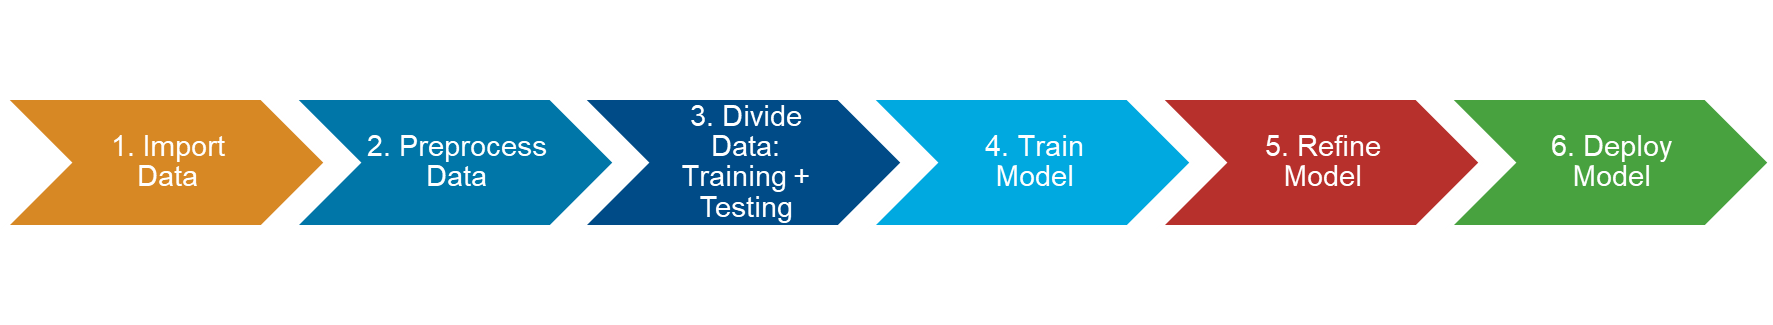

A typical machine learning workflow in MATLAB begins with **importing the dataset **and then visualizing the data to better understand its structure, distribution, and potential anomalies. To prepare the data for modeling, it is **preprocessed** which may include cleaning, normalizing, encoding categorical variables, or handling missing values. 

Once the data is prepared, the next step is to **divide the data into a training set and a test set**. Then we **train the model** using the training set and evaluate its performance on the test set, which contains data it has not seen before, to determine how well it generalizes to new inputs.

We **refine the model **through iterative training and evaluation. Initial results guide adjustments to parameters for the selection of different algorithms. This cycle continues until the model reaches a satisfactory level of performance.

Once a reliable model is developed, we can **deploy the model **in real-world applications. For example, a model trained to detect tumors in brain scans could be integrated into a hospital's radiology system to provide real-time diagnostic support. Such tools can enhance clinical decision-making and help reduce the risk of human error.

 **Understanding Check 5. **

CheckAnswer("Exercise7","To evaluate the model on unseen data.");
CheckAnswer("Exercise8","The initial evaluation results.");
 

## Glossary

**Classification: **A supervised learning task where the goal is to predict discrete labels or categories, such as identifying an image as a "cat" or "dog. (↑ Return to Text)

**Clustering: **An unsupervised learning technique that groups similar data points together based on shared features, revealing hidden patterns or structures in unlabeled data. (↑ Return to Text)

**Machine** **learning: **A technique where computers learn patterns from data to make predictions or decisions without explicit programming. (↑ Return to Text)

**Regression: **A supervised learning task focused on predicting continuous numerical values, such as temperature, price, or age. (↑ Return to Text)

**Supervised** **learning: **A type of machine learning where the model is trained on labeled data to learn the relationship between inputs and known outputs. (↑ Return to Text) 

**Unsupervised learning: **A type of machine learning that analyzes unlabeled data to discover hidden patterns or groupings without predefined categories. (↑ Return to Text)

## Further Exploration

Link to [Machine Learning in MATLAB](https://www.mathworks.com/help/stats/machine-learning-in-matlab.html) to continue learning about Machine learning in MATLAB.

Learn the basics of practical machine learning for classification with MATLAB in the [Machine Learning Onramp](https://matlabacademy.mathworks.com/details/machine-learning-onramp/machinelearning).

[⇦ Return to the main menu](matlab:open('../../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option) % Function to check answers for exercises
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "Exercise1",struct("answer","To recognize patterns in data and make predictions.","hint","How does machine learning help computers find patterns in data and make decisions without being explicitly programmed for each task?"),...
    "Exercise2",struct("answer","It enhances the ability to interpret complex data and make predictions.","hint","How does machine learning machine learning help researchers handle large, complex datasets and uncover patterns that might be hard to detect using traditional methods?"),...
    "Exercise3",struct("answer","It identifies patterns without labeled outputs.","hint","Which type of learning finds structure in data without knowing the correct answers ahead of time?"),...
    "Exercise4",struct("answer","Unsupervised learning","hint","What kind of learning is used when you don't have labeled data but still want to discover patterns or group similar items together?"),...
    "Exercise5",struct("answer","Supervised learning","hint","Which type of learning includes the labels in the training process?"),...
    "Exercise6",struct("answer","Classification assigns inputs to discrete categories, while regression predicts numerical values.","hint","Does the model predict categories like labels or continuous numbers like measurements?"),...
    "Exercise7",struct("answer","To evaluate the model on unseen data.","hint","Why is it important to test the model on data it hasn't seen during training"),...
    "Exercise8",struct("answer","The initial evaluation results.","hint","What information helps decide what to change or improve in the model?"),...
    "Exercise9",struct("answer","It helps analyze complex datasets and identify key patterns.","hint","How do engineers find patterns in large, complex datasets?")...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        StrAns = "You are correct. The answer is """ + option + """";
        disp(StrAns)
    elseif isequal(option,"Select")
        warning("Select a valid option.")
    else
        str = "No, the answer is not """ + option + """" + newline + hint;
        warning("%s",str)

    end
else
    warning("Exercise not found.")
end
end